# Lab 2

Case 6, ECOGUARDAS data, Tlalpan

clear;
clc;

## Load data into matlab

Loading the file's data

url='https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab2/DataECOGUARDAS.csv';
data = readtable(url,"VariableNamingRule", "preserve", "TextType", "string");

Extract data from the vile

hour = data.("Hour");
temp = data.("Temperature");

Convert hour from strings into decimal values

For this part I had to do some online research as I kept having errors

t = duration(hour, "InputFormat", "hh:mm"); %Convert string into h:mm, object type duration
time = double(hours(t)); %Convert the object duration into decimals, 1h 30m is 1.5

Remove possible missing values from the file

idx = ~isnan(time) & ~isnan(temp); %check if there is missing data from loading the file
%only keep data that is not empty
time = time(idx); 
temp = temp(idx);

## Polynomial equation and residuals

Polynomial equation of degree 2

T(t) = at² + bt +c

https://la.mathworks.com/help/symbolic/sym.polynomialdegree.html

p = polyfit(time, temp, 2);

Predict values with original values

fit = polyval(p, time);

Residuals

residuals = temp - fit;

R²

https://matlabscripts.com/r-2-in-matlab

SS_res = sum((temp - fit).^2); %Sum of residuals squared
SS_tot = sum((temp - mean(temp)).^2); %Total sum of the squares
R2 = 1 - SS_res / SS_tot; %Gets the final R²

## Plotting

Smooth the lines in the plot

t_smooth = linspace(min(time), max(time), 500);

[https://la.mathworks.com/help/matlab/ref/plot.html](https://la.mathworks.com/help/matlab/ref/plot.html)

[https://la.mathworks.com/help/matlab/ref/scatter.html](https://la.mathworks.com/help/matlab/ref/scatter.html)

figure;
scatter(time, temp, 50, temp, 'filled');
colormap('turbo');
hold on;
plot(t_smooth, polyval(p, t_smooth));

Error line

plot([time time]', [temp fit]', 'k--');

Formatting the plot

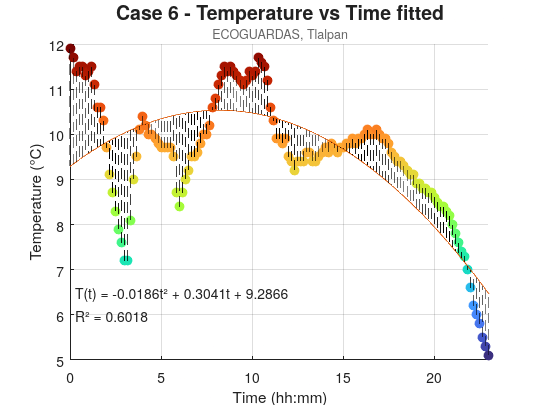

grid on;
xlim([0 23]); 
xlabel('Time (hh:mm)'); 
ylabel('Temperature (°C)');
title('Case 6 - Temperature vs Time fitted','FontSize', 14);
subtitle('ECOGUARDAS, Tlalpan', 'FontSize', 9, 'Color', '#666666'); %weird number but works

text1 = sprintf('T(t) = %.4ft² + %.4ft + %.4f', p(1), p(2), p(3));
text2 = sprintf('R² = %.4f', R2);
text(0.3, 6.5, text1);
text(0.3, 6, text2);
hold off